# Уравнение фон Берталанфи


$$\frac{\mathrm{dV}}{\mathrm{dt}}=\alpha V^{\frac{2}{3}} -\beta \;V,\alpha \;,\beta >0$$


Стационарные точки:


$$\alpha V^{\frac{2}{3}} -\beta \;V=0$$



$$V_1 =0,V_2 ={\left(\frac{\alpha }{\beta \;}\right)}^3$$


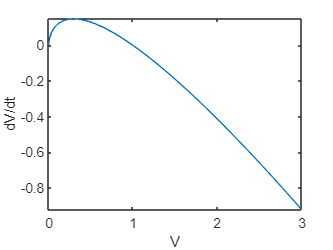

alpha = 1;
beta = 1;
dVdt = @(V) alpha*V.^(2/3) - beta*V;

figure(1)
fplot(dVdt, [0, 3]);
xlabel('V');
ylabel('dV/dt');

## Интегрирование уравнения (по времени)

Время итегрирования:

tspan = [0, 10];

Начальное условие:

V0 = [.5, 1, 2, 2.8];

Производная неизвестной функции $V\left(t\right)$:

dV = @(t, V) alpha*V.^(2/3) - beta*V;

Теперь можно начать интегрировать уравнение (решать по времени) с помощью функции `ode45` (Ordinary Differential Equation).

[t, V] = ode45(dV, tspan, V0);

Визуализация решения:

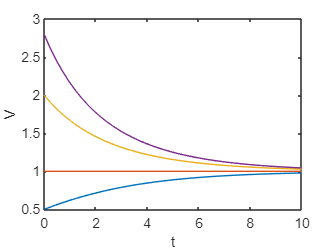

figure(2)
plot(t, V);
xlabel('t');
ylabel('V');

### Сравнение с точным решением

Предложение: точное решение есть:


$$V\left(t\right)={\left\lbrack \frac{\alpha }{\beta \;}+C_1 e^{-\frac{\beta t}{3}} \right\rbrack }^3$$


Найдем константу $C_1$ из начального условия: $V\left(0\right)=V_0$


$${\left\lbrack \frac{\alpha }{\beta \;}+C_1 e^{-\frac{\beta \cdot 0}{3}} \right\rbrack }^3 =V_0$$



$$C_1 =\sqrt[3]{V_0 }-\frac{\alpha }{\beta }$$


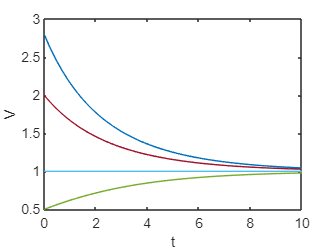

C1 = V0.^(1/3) - alpha/beta;
Vt = @(t) (alpha/beta + C1.*exp(-beta*t/3)).^3;

figure(2);
hold on;
fplot(Vt, tspan)
hold off;

График ошибки - разница между двумя функциями

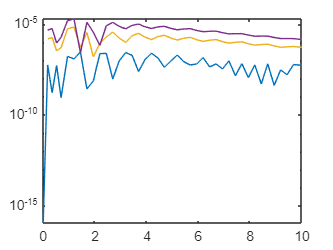

figure(3)
% plot(t, abs(V - Vt(t)))
semilogy(t, abs(V - Vt(t)))